# HW8

set(0,'defaultTextInterpreter','latex'); %trying to set the default

## q5

a = 1;
b = 1/2;

kp = 2.5;
kd = 1;

q0 = [1;0];
tf = 40;

f = @(t,q) [q(2); a*sin(q(1)) - b*(kp*q(1)+kd*q(2))]

f = function_handle with value:
    @(t,q)[q(2);a*sin(q(1))-b*(kp*q(1)+kd*q(2))]


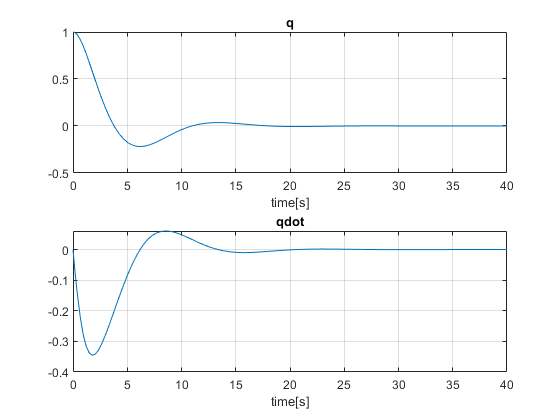


[t,q] = ode45(f, [0,tf], q0);

figure
subplot(2,1,1)
plot(t, q(:,1))
title('q')
xlabel('time[s]')
grid on
subplot(2,1,2)
plot(t, q(:,2))
title('qdot')
xlabel('time[s]')
grid on

## q6

theta = 1.2

theta = 1.2000

k = 2

k = 2


theta_hat0 = -10

theta_hat0 = -10


x0 = [1,0,theta_hat0]

x0 =      1     0   -10


tf = 50

tf = 50

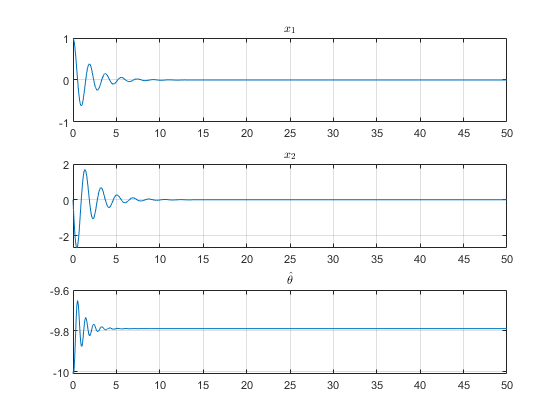


f = @(t,x)  [x(2); -x(1)-x(2)-(theta-x(3))*sin(x(1)); -1/2*(x(1)+2*x(2))*sin(x(1))];

[t,x] = ode45(f, [0,tf], x0);
figure
subplot(3,1,1)
plot(t, x(:,1))
title('$x_1$')
grid on

subplot(3,1,2)
plot(t, x(:,2))
title('$x_2$')
grid on

subplot(3,1,3)
plot(t, x(:,3))
title('$\hat{\theta}$','Interpreter','latex')
grid on